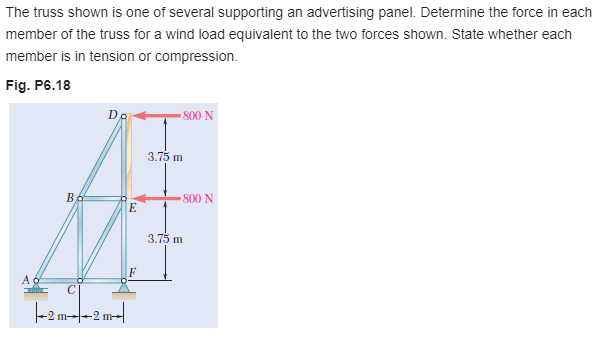

# member data

u = symunit;
E = sym('E');
A = sym('A');
theta = atand(sym(3.75/2))*u.deg;

# truss

t = Truss;
t = t.add('load', 'reaction', {0 'Ray'}, [0 0]);
t = t.add('load', 'reaction', {'Rfx' 'Rfy'}, [4 0]*u.m);
t = t.add('load', 'applied', [-800 0]*u.N, [4 3.75]*u.m);
t = t.add('load', 'applied', [-800 0]*u.N, [4 7.5]*u.m);
t = t.add('joint', 'A', [0 0]);
t = t.add('joint', 'B', [2 3.75]*u.m);
t = t.add('joint', 'C', [2 0]*u.m);
t = t.add('joint', 'D', [4 7.5]*u.m);
t = t.add('joint', 'E', [4 3.75]*u.m);
t = t.add('joint', 'F', [4 0]*u.m);
t = t.add('member', 'Fab', [0 0], [2 3.75]*u.m);
t = t.add('member', 'Fbd', [2 3.75]*u.m, [4 7.5]*u.m);
t = t.add('member', 'Fde', [4 7.5]*u.m, [4 3.75]*u.m);
t = t.add('member', 'Fef', [4 3.75]*u.m, [4 0]*u.m);
t = t.add('member', 'Fcf', [2 0]*u.m, [4 0]*u.m);
t = t.add('member', 'Fac', [0 0], [2 0]*u.m);
t = t.add('member', 'Fbc', [2 3.75]*u.m, [2 0]*u.m);
t = t.add('member', 'Fbe', [2 3.75]*u.m, [4 3.75]*u.m);
t = t.add('member', 'Fce', [2 0]*u.m, [4 3.75]*u.m);

# solution

[us fs rs ua fa ra] = t.solve('factor'); %#ok
ua_vpa = vpa(ua) %#ok

$$ua\_vpa = \left(\begin{array}{cc} u_{1} & -\frac{5600.0}{A\,\text{E}}\,N\,m\\ v_{1} & 0\\ u_{2} & -\frac{29900.0}{A\,\text{E}}\,N\,m\\ v_{2} & \frac{677.5}{A\,\text{E}}\,N\,m\\ u_{3} & -\frac{3200.0}{A\,\text{E}}\,N\,m\\ v_{3} & -\frac{2135.0}{A\,\text{E}}\,N\,m\\ u_{4} & -\frac{70350.0}{A\,\text{E}}\,N\,m\\ v_{4} & \frac{14062.5}{A\,\text{E}}\,N\,m\\ u_{5} & -\frac{30700.0}{A\,\text{E}}\,N\,m\\ v_{5} & \frac{8437.5}{A\,\text{E}}\,N\,m\\ u_{6} & 0\\ v_{6} & 0 \end{array}\right)$$

fa

$$fa = \left(\begin{array}{cc} \mathrm{Fab} & -2550\,N\\ \mathrm{Fac} & 1200\,N\\ \mathrm{Fbc} & 750\,N\\ \mathrm{Fbd} & -1700\,N\\ \mathrm{Fbe} & -400\,N\\ \mathrm{Fce} & -850\,N\\ \mathrm{Fcf} & 1600\,N\\ \mathrm{Fde} & 1500\,N\\ \mathrm{Fef} & 2250\,N \end{array}\right)$$

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ray} & 2250\,N\\ \mathrm{Rfx} & 1600\,N\\ \mathrm{Rfy} & -2250\,N \end{array}\right)$$

clear ua_vpa;